Zayid Oyelami

Problem Set 4

April 12 2019

## Problem 1

### Aligning Faces

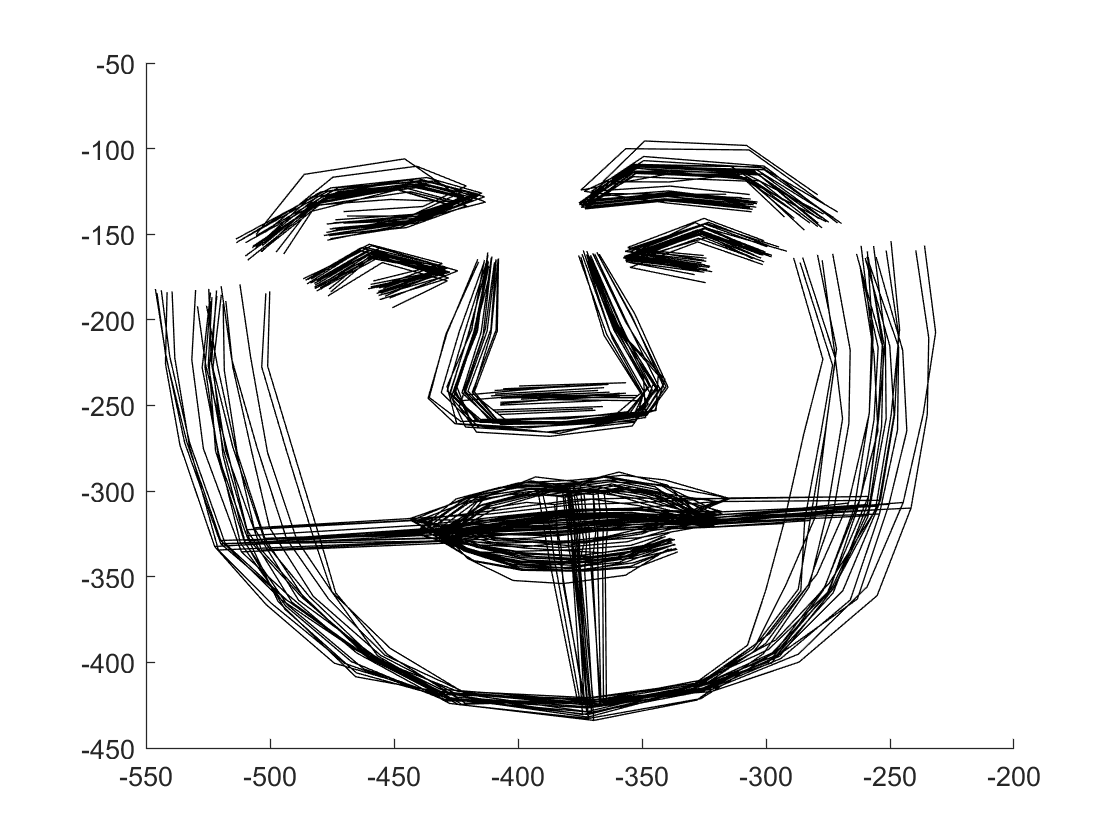

figure()
N =21;
for j = 1:N
    drawFaceParts( -aligned(:,:,j), 'k-' )
    hold on
end

Xtrain = reshape(aligned,[],N);
hiddenSize = round([1 3 10 100]/100 *136);
for i = 1:length(hiddenSize)
    autoenc = trainAutoencoder(Xtrain,hiddenSize(i));
    Xpred = predict(autoenc,Xtrain);
    mseError(i) = mse(Xtrain-Xpred);
    Xnew{i} = Xpred;
end

The increase in the number of hidden layers leads to an increase the better reconstruction. This would make sense because the hidden layers correspond to the number features reduce before being reconstructed. Hence, if you have all the feautres like in the 100% hidden layers, then we have a complete reconstruction with little to no error. However, we can see that we do just as well with even a portion of the hidden layers.

### No Regularity

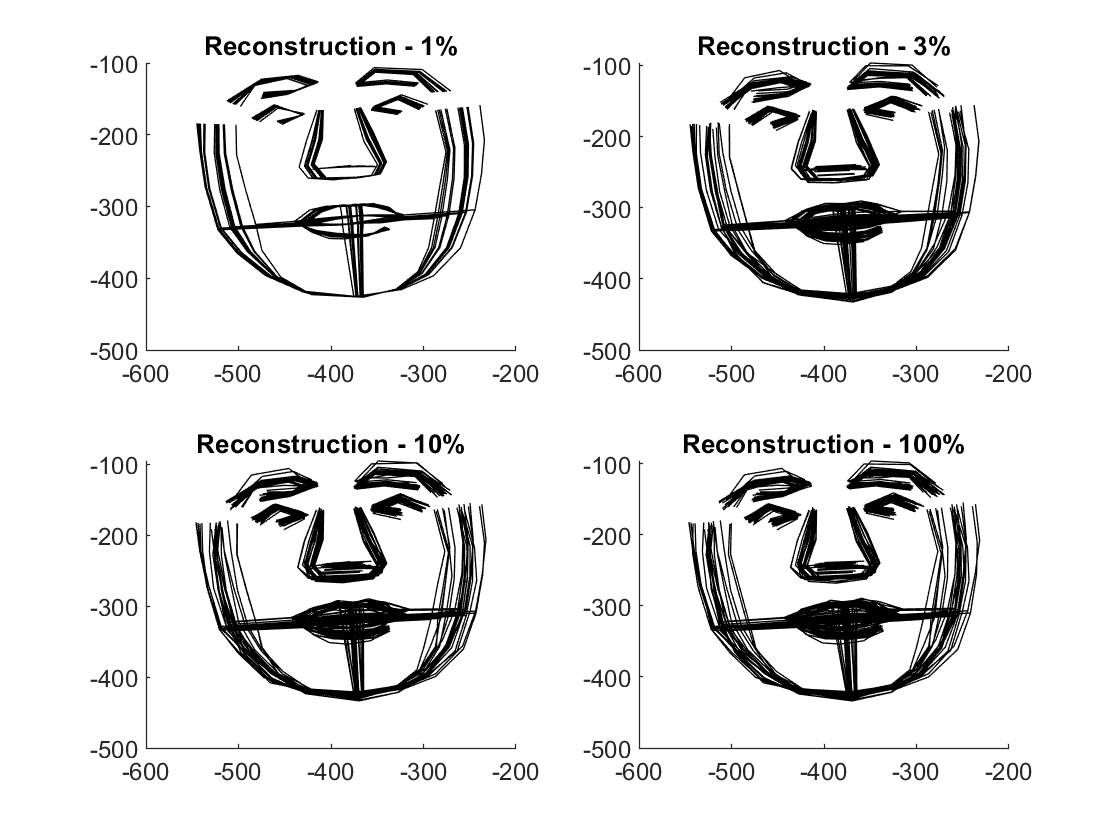

figure()
per = [1 3 10 100];
for i = 1:length(hiddenSize)
    Xpred1 = reshape(Xnew{i},[],2,N);
    subplot(2,2,i)
    for j = 1:N
        drawFaceParts( -Xpred1(:,:,j), 'k-' )
        hold on
    end
    ttl = sprintf('Reconstruction - %d%%',per(i));
    title(ttl)
end

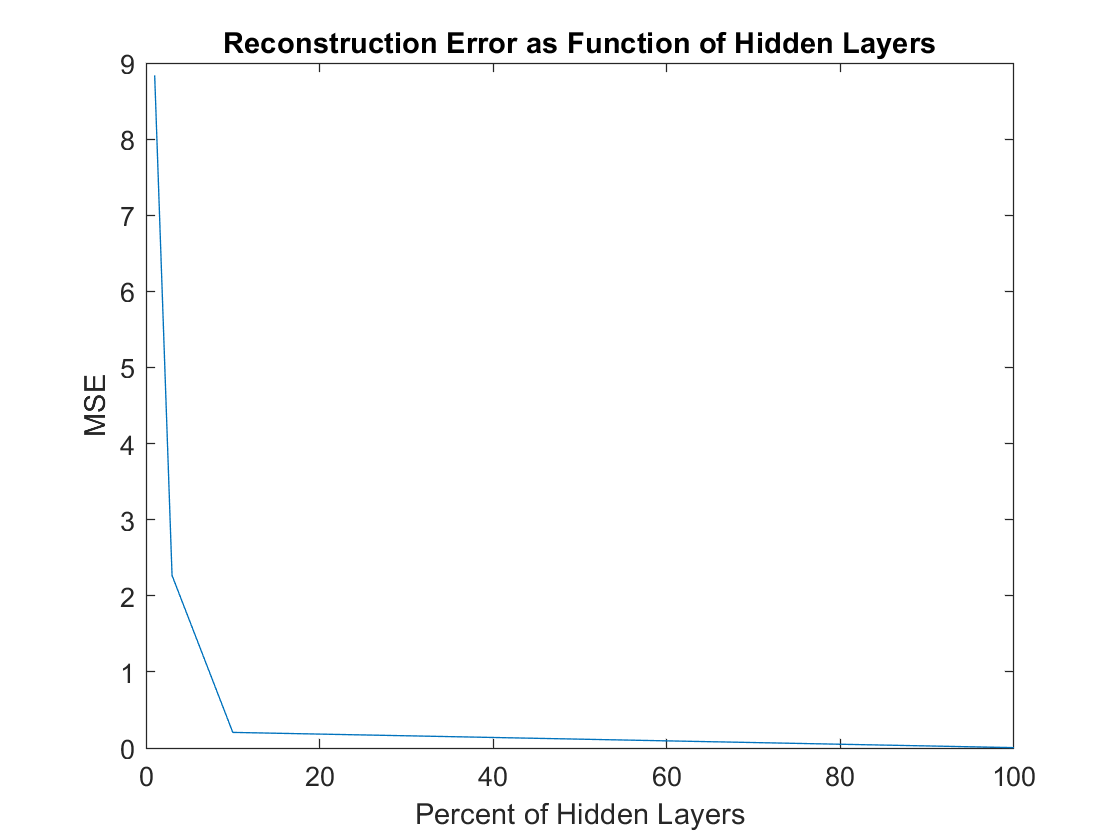

figure()
plot(per, mseError)
title('Reconstruction Error as Function of Hidden Layers')
xlabel("Percent of Hidden Layers")
ylabel('MSE')

### Regularity

Xtrain = reshape(aligned,[],N);
hiddenSize = round([1 3 10 100]/100 *136);
w = (1:4:10)/10;
for i = 1:length(hiddenSize)
    for j = 1:length(w)
        autoenc = trainAutoencoder(Xtrain,hiddenSize(i),'L2WeightRegularization',w(j));
        Xpred = predict(autoenc,Xtrain);
        mseError(i,j) = mse(Xtrain-Xpred);
        Xnew{i,j} = Xpred;
    end
end

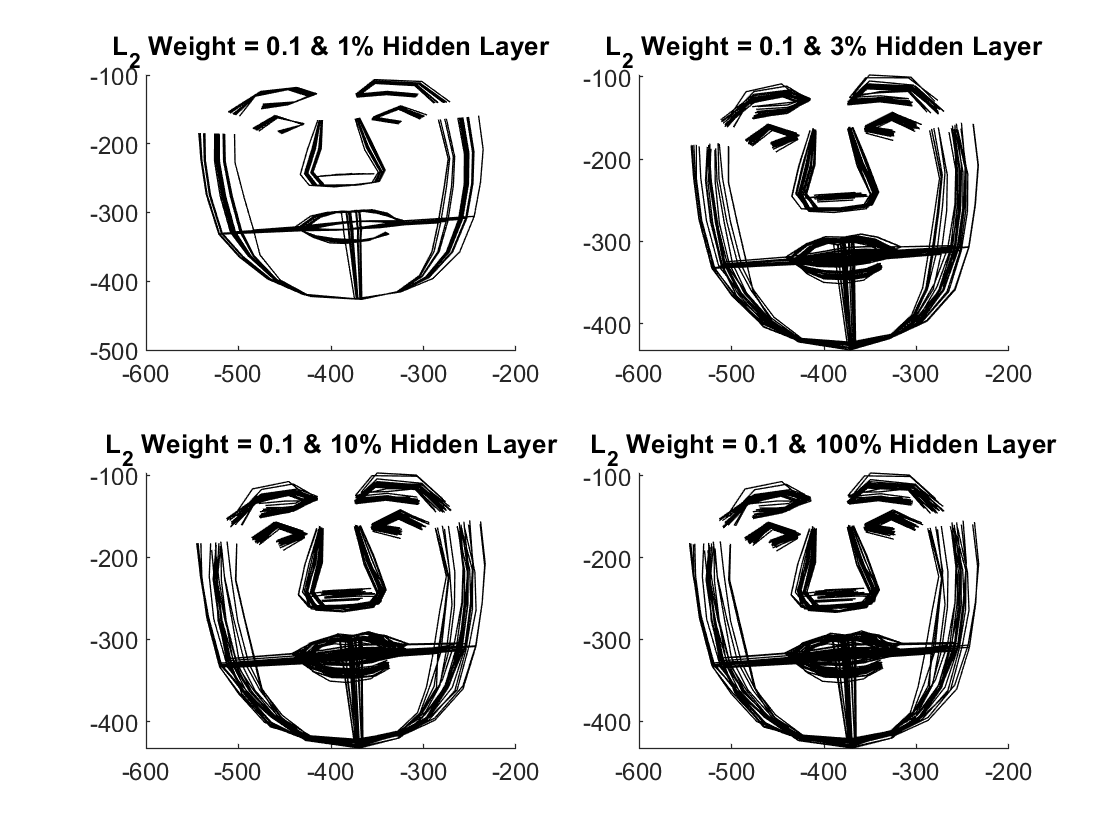

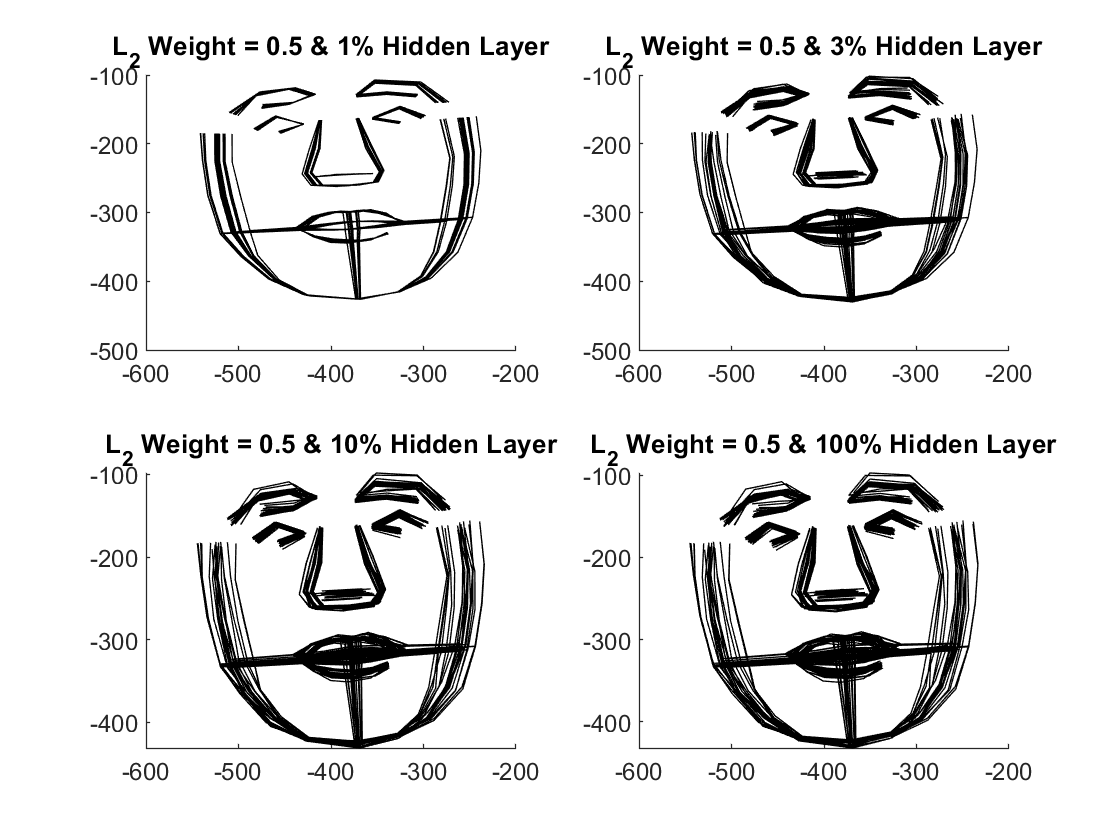

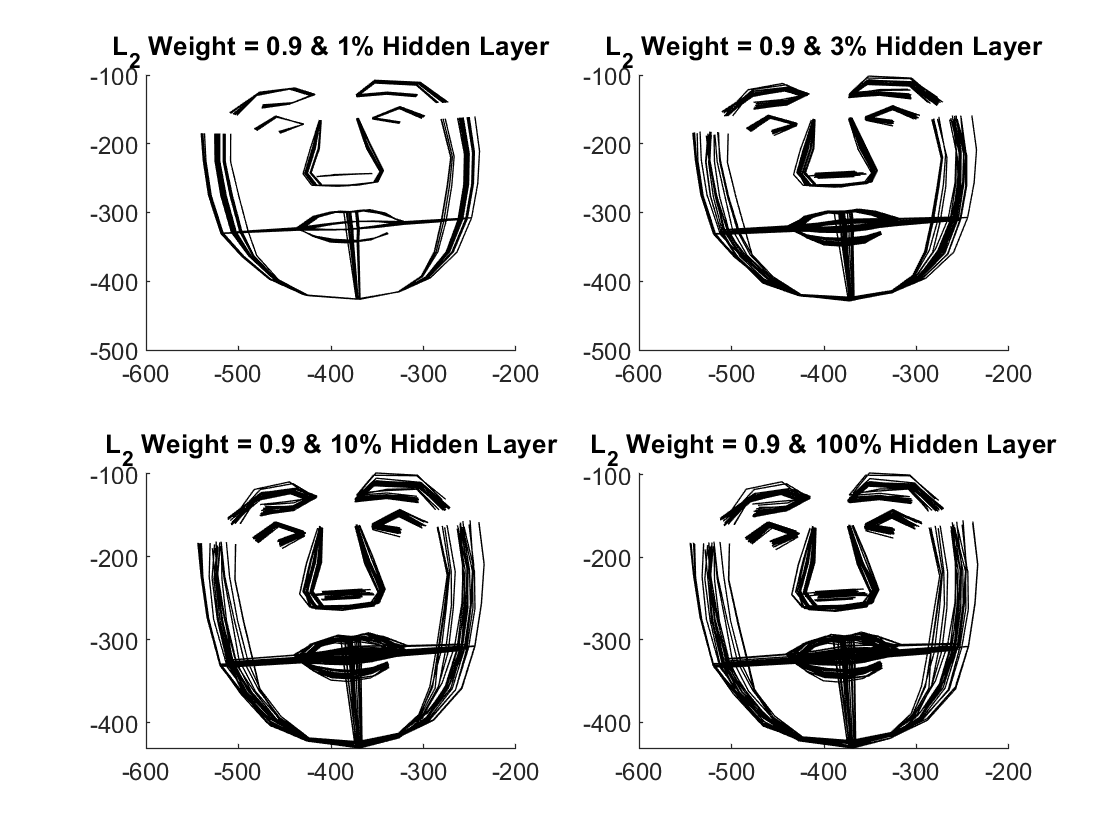


per = [1 3 10 100];
for j = 1:length(w)
    figure()
    for i = 1:length(hiddenSize)
        Xpred1 = reshape(Xnew{i,j},[],2,N);
        subplot(2,2,i)
        for k = 1:N
            drawFaceParts( -Xpred1(:,:,k), 'k-' )
            hold on
        end
        ttl = sprintf('L_2 Weight = %.1f & %d%% Hidden Layer',w(j),per(i));
        title(ttl)
    end
    
end

Regularity

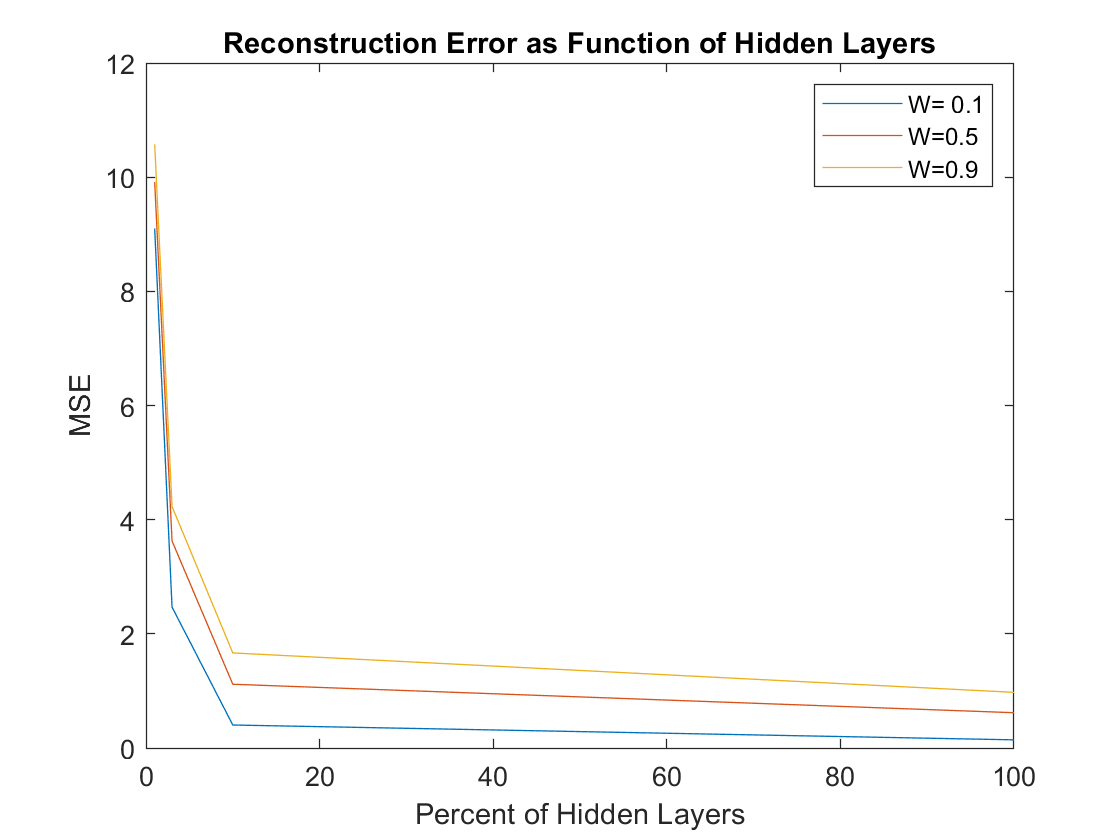

figure()
plot(per, mseError(:,1),per, mseError(:,2),per, mseError(:,3))
title('Reconstruction Error as Function of Hidden Layers')
xlabel("Percent of Hidden Layers")
ylabel('MSE')
legend('W= 0.1','W=0.5','W=0.9')

table(mseError)

ans = 4×1 table
              mseError           
    _____________________________

     9.1011     9.9139     10.574
     2.4683     3.6266     4.2304
    0.40275     1.1167     1.6654
    0.14301    0.61816    0.97495


It's clear that the error decreases as the number of hidden layers increases, but we can see that weights have an inverse relationship as it increases, the error also increases. This is sensible because we are placing a stricter regularization term on our reconstruction to prevent overfitting, so that our model generalizes well.

## Problem 2

T = readtable('iris.txt');
T2= T(ismember(T.Species,{'virginica','versicolor'}),:);
rows = strcmp(T2.Species,'versicolor');
T2.Species(rows) = {0};

rows = strcmp(T2.Species,'virginica');
T2.Species(rows) = {1};
X = table2array(T2(:,1:4))';
Y = cell2mat(T2.Species);

Xtrain = X(:,[1:30,51:80]);
Ytrain = Y([1:30,51:80]);
Xtest = X(:,[31:50,81:100]);
Ytest = Y([31:50,81:100]);

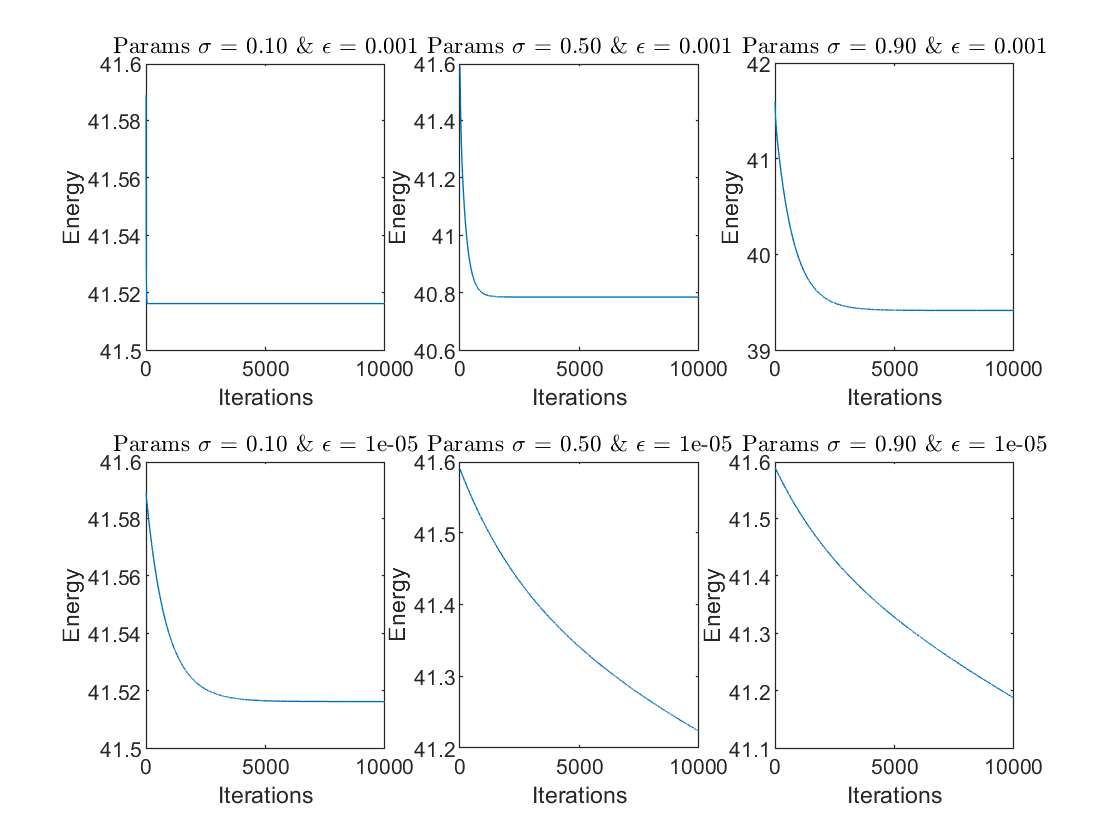

sigma = [0.1 0.5 0.9];
eta = [0.001 0.00001];
max_its = 10000;

for i = 1:2
    for j = 1:3
        subplot(2,3,3*(i-1)+j)
        [ ~,e(i,j),~ ] = blogistic_reg( Xtrain, Ytrain,Xtest,Ytest, max_its, eta(i),sigma(j) );
        X = sprintf('Error Rate = %0.3f',e(i,j));
    end
end

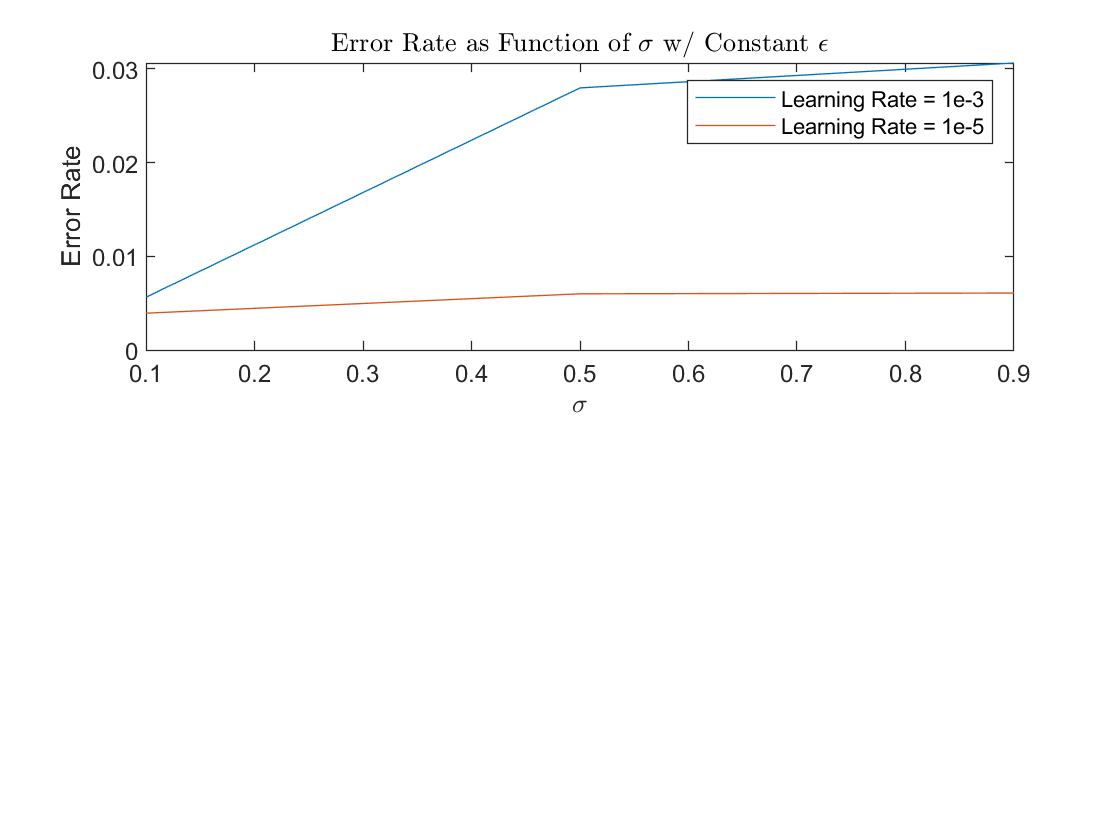

figure()
subplot(2,1,1)
plot(sigma,e)
xlabel('$\sigma$','Interpreter','latex')
ylabel('Error Rate')
legend('Learning Rate = 1e-3','Learning Rate = 1e-5')
title('Error Rate as Function of $ \sigma $ w/ Constant $ \epsilon $','Interpreter','latex')

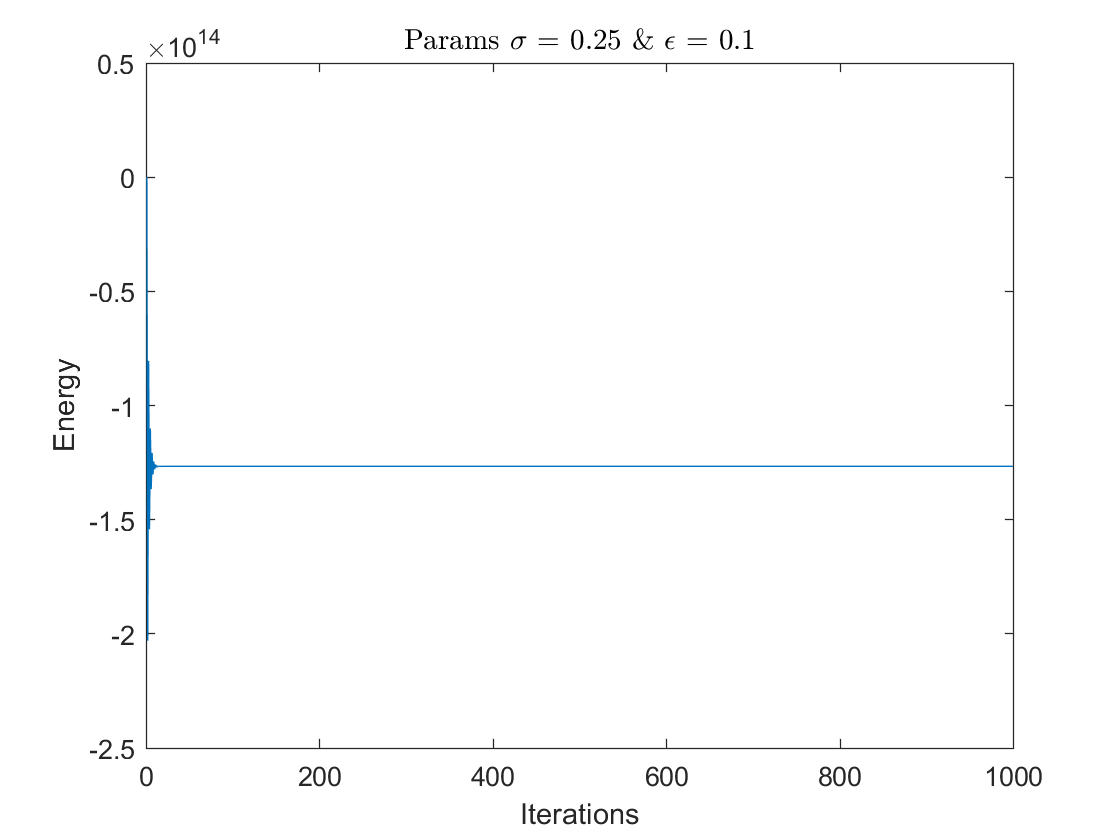

w = 	1.0e+05 *

    0.0000
    0.0003
    0.0000
    0.0001
    0.0000
    0.0976
    3.6277
   -0.0165
    0.0038
    0.0000


e = -69

U = 	1.0e+14 *

    0.0000   -2.0300   -0.8046   -1.5423   -1.1006   -1.3659   -1.2068   -1.3023   -1.2451   -1.2794   -1.2588   -1.2712   -1.2638   -1.2682   -1.2655   -1.2671   -1.2662   -1.2668   -1.2664   -1.2666   -1.2665   -1.2666   -1.2665   -1.2666   -1.2665   -1.2665   -1.2665   -1.2665   -1.2665   -1.2665   -1.2665   -1.2665   -1.2665   -1.2665   -1.2665   -1.2665   -1.2665   -1.2665   -1.2665   -1.2665   -1.2665   -1.2665   -1.2665   -1.2665   -1.2665   -1.2665   -1.2665   -1.2665   -1.2665   -1.2665


Xtrain= X(1:59,:)';
Ytrain = Y(1:59);
Xtest = X(60:end,:)';
Ytest = Y(60:end);

[ w,e,U] = blogistic_reg( Xtrain, Ytrain,Xtest,Ytest, 1000, 0.1,0.25 )

We see that a higher learning rate leads to a lower error rate. However, when the learning rate was too low the criterion was met within the first iteration. Additionally, the increase in standard deviation causes a slight increase in error rate, which would make sense due to implication of higher variance in the data. Furthermore, we see that the energy converges for all $\epsilon$ = 0.001, but not for $\epsilon$  = 0.00001. This is probably because the learning rate is so low that it takes a lot more iterations to reach convergence.

function [ w,e,U] = blogistic_reg( X, y,Xtest,Ytest, max_its, eta,sigma )
%LOGISTIC_REG Learn logistic regression model using gradient descent
%   Inputs:
%       X : data matrix (without an initial column of 1s) -- (d x N)
%       y : data labels (plus or minus 1) -- (N x 1)
%       w_init: initial value of the w vector (d+1 dimensional) (1 x d+1)
%       max_its: maximum number of iterations to run for
%       eta: learning rate
    
%   Outputs:
%       w : weight vector
%       e_in : in-sample error (as defined in LFD)
    % Initial
    [d,N] = size(X);
    [d,N2] = size(Xtest);
    X2 = [ones(1,N); X];
    Xtest = [ones(1,N2); Xtest];
    w = zeros(d+1,max_its);
    
    grad = zeros(d+1,N);
    Grad = zeros(d+1,max_its);
    for t = 1:max_its-1
        for n = 1:N
            term1 = (1-y(n))*X2(:,n);
            term2a = X2(:,n)*exp(-X2(:,n)'*w(:,t));
            term2b = 1 + exp(-X2(:,n)'*w(:,t));
            term2 = term2a/term2b;
            grad(:,n) = term1 - term2;      
        end
        Grad(:,t) = (mean(grad,2)+ w(:,t)./sigma^2);
        term1 = ((1-y)'*X2')*w(:,t);
        term2 = sum(log(1 + exp(-X2'*w(:,t))));
        term3 = (norm(w(:,t))^2)./(2*sigma^2);
        U(t) = term1 + term2 + term3;
        
        w(:,t+1) = w(:,t) - eta*Grad(:,t);
        if norm(w(:,t+1)) < 1e-6
            break
        end
    end
    w = w(:,t+1);
    Ypred = 1./(1+exp(-Xtest'*w));
    e = mean(Ypred-Ytest);
    

    plot(U)
    ttl = sprintf("Params $\\sigma$ = %.2f \\& $\\epsilon$ = %.5g",sigma,eta);
    title(ttl,'Interpreter','latex');
    xlabel('Iterations')
    ylabel('Energy')
end